# Community size spectrum and HTL mortality in a water column

The NUM water column model is run for a range of values of the higher trophic level (HTL) mortality coefficient. For each run the Sheldon community spectrum is integrated over depth and averaged over the last year (the seasonal cycle).

The commit and date this was last run for are printed below, so the stored output can be traced back to the state of the code that produced it.

% Make the NUM matlab functions available:
addpath('../matlab');

printStatus();

Run for commit d0b92d0 on branch Develop, working tree modified
Run on 2026-10-02 14:06


## Settings

The HTL mortality is set as in setupNUMmodel: "quadratic", not declining with size, and only affecting copepods. Only the coefficient is varied; the setup default is 0.006 (mugC/l*day)^-1.

mortHTL = [0 0.001 0.003 0.006 0.01 0.03]; % HTL mortality coefficients
lat = 60;       % Latitude of the water column
lon = -15;      % Longitude of the water column
tEnd = 5*365;   % Simulation time (days)
mHTL = 1;       % Size where the HTL mortality starts (mugC)

## Simulations

nRuns = length(mortHTL);
sims = cell(1, nRuns);

for iRun = 1:nRuns
    fprintf('Run %i of %i: mortHTL = %g\n', iRun, nRuns, mortHTL(iRun));

    p = setupNUMmodel();
    p = parametersWatercolumn(p);
    p.tEnd = tEnd;
    % Override the default HTL mortality coefficient set by setupNUMmodel:
    setHTL(mortHTL(iRun), mHTL, true, false, true);

    sims{iRun} = simulateWatercolumn(p, lat, lon);
end

Run 1 of 6: mortHTL = 0


Preparing simulation
Starting simulation
Solving time:  0:00:01


Run 2 of 6: mortHTL = 0.001


Preparing simulation
Starting simulation
Solving time:  0:00:00


Run 3 of 6: mortHTL = 0.003


Preparing simulation
Starting simulation
Solving time:  0:00:00


Run 4 of 6: mortHTL = 0.006


Preparing simulation
Starting simulation
Solving time:  0:00:00


Run 5 of 6: mortHTL = 0.01


Preparing simulation
Starting simulation
Solving time:  0:00:00


Run 6 of 6: mortHTL = 0.03


Preparing simulation
Starting simulation
Solving time:  0:00:00


## Depth-integrated community spectrum

The biomass is integrated over depth (mugC/l * m = mgC/m2, converted to gC/m2) and averaged over the last year before the Sheldon spectrum is calculated.

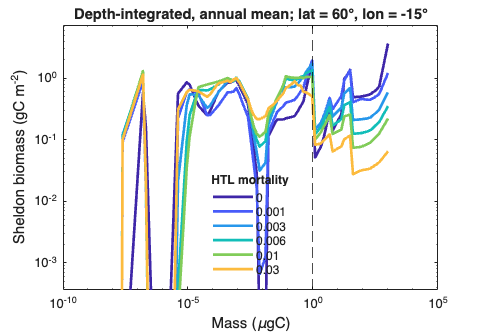

BSheldon = [];
for iRun = 1:nRuns
    sim = sims{iRun};
    ixAve = sim.t > sim.t(end) - 365;
    Bint = squeeze(sum(sim.B(ixAve,:,:) .* reshape(sim.dznom, 1, [], 1), 2))/1000;
    Bmean = mean(Bint, 1);
    [mc, BSheldon(iRun,:)] = calcCommunitySpectrum(Bmean, sim, 1);
end

figure('Position', [100 100 640 440])
colors = parula(nRuns+1);
for iRun = 1:nRuns
    loglog(mc, BSheldon(iRun,:), 'linewidth', 2, 'color', colors(iRun,:), ...
        'DisplayName', sprintf('%g', mortHTL(iRun)))
    hold on
end
xline(mHTL, '--k', 'HandleVisibility', 'off')
hold off
lgd = legend('location', 'best', 'box', 'off');
lgd.Title.String = 'HTL mortality';
xlabel('Mass (\mugC)')
ylabel('Sheldon biomass (gC m^{-2})')
ylim([max(BSheldon(:))*1e-4, 2*max(BSheldon(:))])
title(sprintf('Depth-integrated, annual mean; lat = %g%s, lon = %g%s', ...
    lat, char(176), lon, char(176)))